% Gabriel Werpel Fernandes
% April 2024

## Load File and Extract Data

% Close all figures and clear variables
clc;
close all;
clearvars;

% User selects BDF file using a dialog box
[filename, path] = uigetfile('.\*.bdf', 'Select a BDF file');

% Construct the full file path
fullFilePath = fullfile(path, filename);

% Read header information using Fieldtrip toolbox
hdr = read_biosemi_bdf(fullFilePath);

% Read raw EEG data, skipping the first sample and extracting all samples
EEG_raw = read_biosemi_bdf(fullFilePath, hdr, hdr.nSamplesPre, hdr.nSamples)';
EEG_raw = EEG_raw(2:end, 1:end-1); % Remove first row (garbage value) and last column (event data)

% Select data (e.g., from the occipital channel 'Oz')
channel_select = 'A16';  % Channel label for Oz
channel_index = find(strcmp(hdr.label, channel_select));  % Find index of Oz in the label list
EEG_Oz1 = EEG_raw(:, channel_index);  % Extract Oz channel data

## Filter EEG Data

% Adjust the bandpass filter from 2 to 80 Hz - 6th order zero-phase Butterworth IIR
Fc_BP = [2 80]; % New bandpass frequency range
Wn_BP = Fc_BP/(hdr.Fs/2); % Normalize by Nyquist frequency

% Create bandpass filter coefficients
[B_BP, A_BP] = butter(3, Wn_BP, 'bandpass');

% Apply bandpass filter
EEG_Oz_filtered_BP = filtfilt(B_BP, A_BP, EEG_Oz1);

% Set up 48-52 Hz band stop filter - 6th order zero-phase Butterworth IIR
Fc_BS = [48 52]; % Band stop frequency range
Wn_BS = Fc_BS/(hdr.Fs/2); % Normalize by Nyquist frequency

% Create band stop filter coefficients
[B_BS, A_BS] = butter(3, Wn_BS, 'stop');

% Apply band stop filter
EEG_Oz_filtered = filtfilt(B_BS, A_BS, EEG_Oz_filtered_BP);


## Plot EEG Time-Series - Raw and Filtered

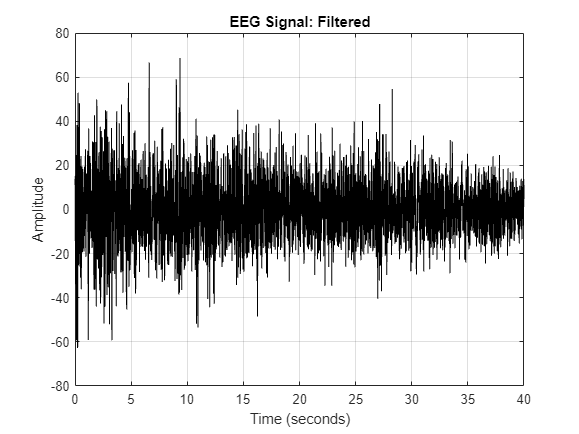

time = (1:length(EEG_Oz_filtered))/hdr.Fs;
% Plotting
figure('Position', [100, 100, 800, 600]);
plot(time, EEG_Oz_filtered, 'k');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('EEG Signal: Filtered');
xlim([0 40]);
grid on;

## Segment EEG Data

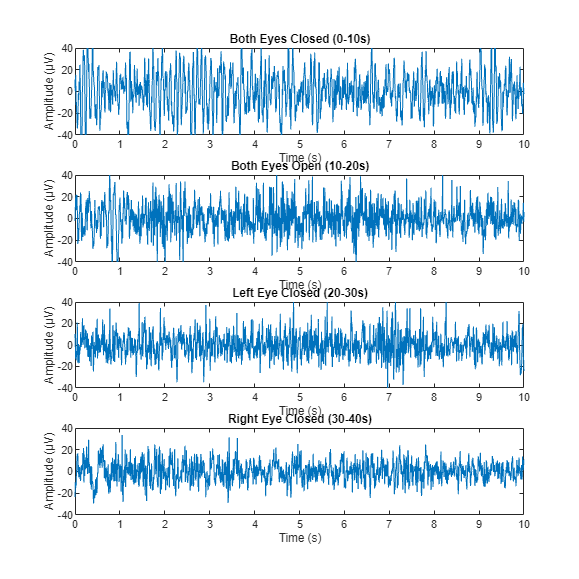

% Constants
sampling_rate = hdr.Fs; % Sampling frequency from the header
segment_duration = 10; % Duration of each segment in seconds

% Calculate number of samples per segment
samples_per_segment = segment_duration * sampling_rate;

% Segmentation of the EEG data
% BE_Closed: Both Eyes Closed (0-10 seconds)
BE_Closed = EEG_Oz_filtered(1:samples_per_segment);

% BE_Open: Both Eyes Open (10-20 seconds)
BE_Open = EEG_Oz_filtered(samples_per_segment+1:2*samples_per_segment);

% LE_Closed: Left Eye Closed (20-30 seconds)
LE_Closed = EEG_Oz_filtered(2*samples_per_segment+1:3*samples_per_segment);

% RE_Closed: Right Eye Closed (30-40 seconds)
RE_Closed = EEG_Oz_filtered(3*samples_per_segment+1:4*samples_per_segment);

% Plotting each segment to verify segmentation:
figure;
subplot(4,1,1);
plot((0:samples_per_segment-1)/sampling_rate, BE_Closed);
title('Both Eyes Closed (0-10s)');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
ylim([-40 40]);

subplot(4,1,2);
plot((0:samples_per_segment-1)/sampling_rate, BE_Open);
title('Both Eyes Open (10-20s)');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
ylim([-40 40]);

subplot(4,1,3);
plot((0:samples_per_segment-1)/sampling_rate, LE_Closed);
title('Left Eye Closed (20-30s)');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
ylim([-40 40]);

subplot(4,1,4);
plot((0:samples_per_segment-1)/sampling_rate, RE_Closed);
title('Right Eye Closed (30-40s)');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
ylim([-40 40]);


% Adjust subplot spacing
set(gcf, 'Position', [100, 100, 800, 800]); % Adjust the figure size
subplots = findall(gcf, 'Type', 'axes');
for i = 1:length(subplots)
    subplots(i).Position(4) = 0.15; % Adjust the height of each subplot
end

## Fourier Spectrum

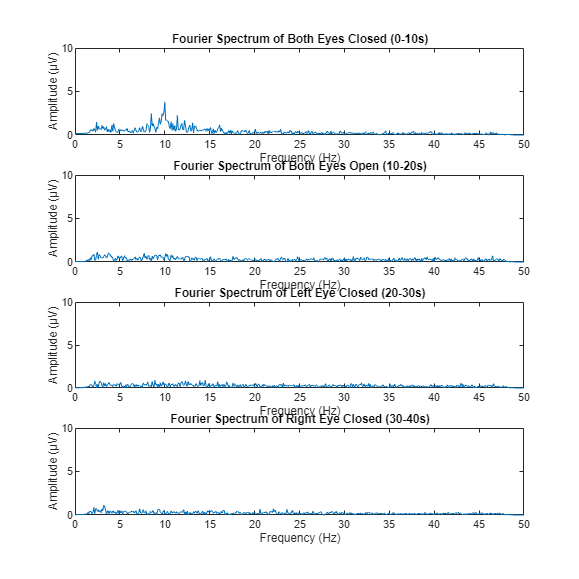

% Constants
n = length(BE_Closed); % Number of samples in each EEG segment
f = (0:n/2)*(sampling_rate/n); % Frequency range up to Nyquist frequency
half_n = n/2 + 1; % Number of points in the FFT output to consider (positive frequencies)

% Initialize spectra matrix for storing FFT results up to Nyquist frequency
spectra = zeros(half_n, 4);

% Compute FFT for each segment and retain the amplitude in microvolts
fft_BE_Closed = fft(BE_Closed, n);
spectra(:,1) = abs(fft_BE_Closed(1:half_n)/n);

fft_BE_Open = fft(BE_Open, n);
spectra(:,2) = abs(fft_BE_Open(1:half_n)/n);

fft_LE_Closed = fft(LE_Closed, n);
spectra(:,3) = abs(fft_LE_Closed(1:half_n)/n);

fft_RE_Closed = fft(RE_Closed, n);
spectra(:,4) = abs(fft_RE_Closed(1:half_n)/n);

% Plot each spectrum
figure;
subplot(4,1,1);
plot(f, spectra(:,1));
title('Fourier Spectrum of Both Eyes Closed (0-10s)');
xlabel('Frequency (Hz)');
ylabel('Amplitude (μV)');
xlim([0 50]);
ylim([0 10]);

subplot(4,1,2);
plot(f, spectra(:,2));
title('Fourier Spectrum of Both Eyes Open (10-20s)');
xlabel('Frequency (Hz)');
ylabel('Amplitude (μV)');
xlim([0 50]);
ylim([0 10]);

subplot(4,1,3);
plot(f, spectra(:,3));
title('Fourier Spectrum of Left Eye Closed (20-30s)');
xlabel('Frequency (Hz)');
ylabel('Amplitude (μV)');
xlim([0 50]);
ylim([0 10]);

subplot(4,1,4);
plot(f, spectra(:,4));
title('Fourier Spectrum of Right Eye Closed (30-40s)');
xlabel('Frequency (Hz)');
ylabel('Amplitude (μV)');
xlim([0 50]);
ylim([0 10]);

% Adjust subplot spacing
set(gcf, 'Position', [100, 100, 800, 800]); % Adjust the figure size
subplots = findall(gcf, 'Type', 'axes');
for i = 1:length(subplots)
    subplots(i).Position(4) = 0.15; % Adjust the height of each subplot
end

## FFT dB vs Freq

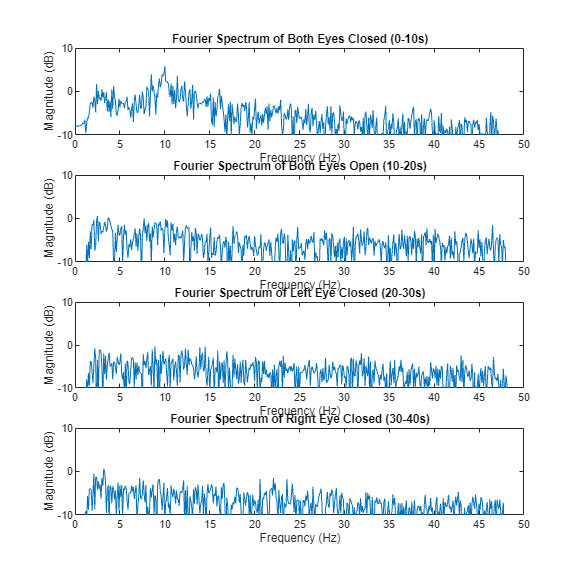

% Constants
n = length(BE_Closed); % Number of samples in each EEG segment
f = (0:n/2)*(sampling_rate/n); % Frequency range up to Nyquist frequency
half_n = n/2 + 1; % Number of points in the FFT output to consider (positive frequencies)

% Initialize spectra matrix for storing FFT results up to Nyquist frequency
spectra = zeros(half_n, 4);

% Compute FFT for each segment, get the magnitude, and convert to dB scale
fft_BE_Closed = fft(BE_Closed, n);
spectra(:,1) = 10*log10(abs(fft_BE_Closed(1:half_n)/n));

fft_BE_Open = fft(BE_Open, n);
spectra(:,2) = 10*log10(abs(fft_BE_Open(1:half_n)/n));

fft_LE_Closed = fft(LE_Closed, n);
spectra(:,3) = 10*log10(abs(fft_LE_Closed(1:half_n)/n));

fft_RE_Closed = fft(RE_Closed, n);
spectra(:,4) = 10*log10(abs(fft_RE_Closed(1:half_n)/n));

% Plot each spectrum
figure;
subplot(4,1,1);
plot(f, spectra(:,1));
title('Fourier Spectrum of Both Eyes Closed (0-10s)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 50]);
ylim([-10 10]);

subplot(4,1,2);
plot(f, spectra(:,2));
title('Fourier Spectrum of Both Eyes Open (10-20s)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 50]);
ylim([-10 10]);

subplot(4,1,3);
plot(f, spectra(:,3));
title('Fourier Spectrum of Left Eye Closed (20-30s)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 50]);
ylim([-10 10]);

subplot(4,1,4);
plot(f, spectra(:,4));
title('Fourier Spectrum of Right Eye Closed (30-40s)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 50]);
ylim([-10 10]);

% Adjust subplot spacing
set(gcf, 'Position', [100, 100, 800, 800]); % Adjust the figure size
subplots = findall(gcf, 'Type', 'axes');
for i = 1:length(subplots)
    subplots(i).Position(4) = 0.15; % Adjust the height of each subplot
end